# Calibrating & Simulating Natural Gas Spot Prices

This example demonstrates calibrating an Ornstein-Uhlenbeck mean reverting stochastic model from historical data of natural gas prices. The model is then used to simulate the spot prices into the future using the Stochastic Differential Equation Simulation engine in Econometrics Toolbox.

## Import Historical Data

The data can be imported from a MAT-file in *Data* folder. The data set contains daily spot prices for natural gas at Henry Hub from 1998 to 2018 (see [Step0_PreparePRMIAChallengeData.mlx](matlab:edit Step0_PreparePRMIAChallengeData.mlx) for details and sources).

clearvars
load Data\ngPrices.mat
tail(ngPrices)

ans = 8×5 timetable
            Time            RNGWHHDd    RNGC1d    RNGC2d    RNGC3d    RNGC4d
    ____________________    ________    ______    ______    ______    ______

    04-Jan-2019 00:00:00       2.8      3.044     2.905     2.688      2.66 
    07-Jan-2019 00:00:00      2.74      2.944     2.847     2.677     2.662 
    08-Jan-2019 00:00:00      2.89      2.967     2.835     2.695     2.683 
    09-Jan-2019 00:00:00      2.92      2.984      2.84     2.706     2.696 
    10-Jan-2019 00:00:00      2.95      2.969     2.813     2.706     2.698 
    11-Jan-2019 00:00:00      2.95      3.099     2.945     2.769     2.747 
    14-Jan-2019 00:00:00      3.36      

Note that there are missing values in the data set, such as above.  We will fill the missing values with the previously observed price and then remove the remining missing data set at the head of the table.

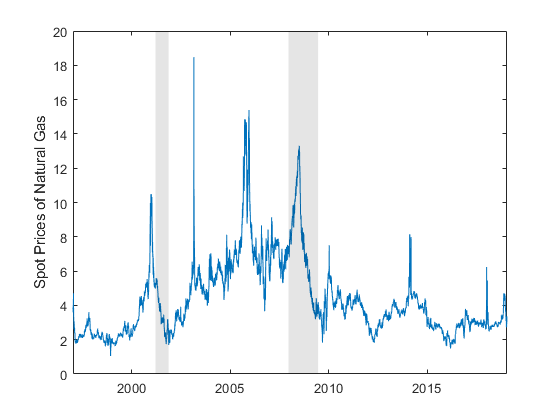

ngPrices = fillmissing(ngPrices,'previous'); % enough data to fill
ngPrices = rmmissing(ngPrices); % remove remaining missing data
Dates = ngPrices.Time;
S = ngPrices.RNGWHHDd;

plot(Dates,S)
ylabel('Spot Prices of Natural Gas')
recessionplot

## The Model

The model used for simulating the Natural Gas prices is an Ornstein-Uhlenbeck brownian motion with mean reverting drift. This model is fit to the log of natural gas prices. The discrete-time equation of this model can be written as,


$$ \Delta x_t = \alpha(\mu - x_t)\Delta t + \sigma dz_t, \textrm{ where } dz_t \sim N(0, \sqrt\Delta_t) $$



$$ \alpha = \textrm{ Mean Reversion Rate}$$



$$ \mu = \textrm{ Mean level} $$



$$ \sigma = \textrm { Volatility } $$


This model can be calibrated to historical data by performing a linear regression between log prices and their first difference. Specifically, the equation can be rewritten as,


$$ \frac{\Delta x_t}{\Delta t} = - \alpha x_t + \alpha\mu + \frac{\sigma}{\Delta t} dz_t $$


## Calibrate Parameters

The reversion rate and mean level can be calculated from the coefficients of a linear fit between the log prices and their first difference scaled by the time interval parameter. All quantities are specified on an annual scale. 

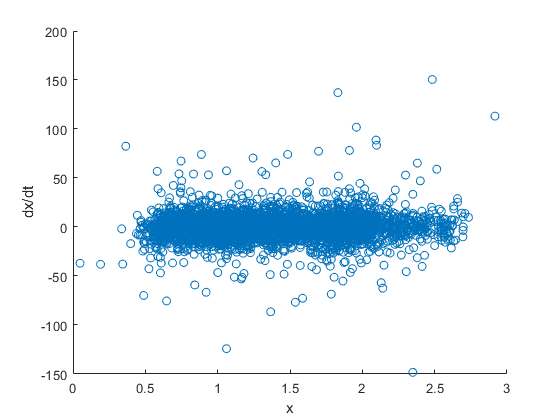

x = log(S);
dx = diff(x);
dt = 1/261; % Time in years (261 observations per year)
dxdt = dx/dt;
x(1) = []; % To ensure the number of elements in x and dxdt match

scatter(x,dxdt)
xlabel('x')
ylabel('dx/dt')

Fit a linear trend to estimate mean reversion parameters

mdl = fitlm(x, dxdt,'linear','VarNames',{'dxdt','x'})

mdl = Linear regression model:
    x ~ 1 + dxdt

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -1.7261     0.49313    -3.5003    0.00046839
    dxdt            1.2665     0.34403     3.6814    0.00023413


Number of observations: 5564, Error degrees of freedom: 5562
Root Mean Squared Error: 11.8
R-squared: 0.00243,  Adjusted R-Squared 0.00225
F-statistic vs. constant model: 13.6, p-value = 0.000234

revRate   = -mdl.Coefficients.Estimate(1)

revRate = 1.7261

meanLevel = mdl.Coefficients.Estimate(2)/revRate

meanLevel = 0.7337

res = dxdt - predict(mdl,x);
vol = std(res) * sqrt(dt)

vol = 0.7281

## Create an Ornstein-Uhlenbeck mean reverting drift model

An Ornstein-Uhlenbeck model is a special case of a Hull-White-Vasicek model with constant volatility. The HWV constructor is used to setup an SDE model with the parameters estimated above. The start state of the model is set to the last observed log spot price. This model can be easily extend to accommodate the forward curve and option prices by setting the meanLevel and volatility parameters to be functions of time.

OUmodel = hwv(revRate, meanLevel, vol,  'StartState', x(end))

OUmodel =    Class HWV: Hull-White/Vasicek
   ----------------------------------------
     Dimensions: State = 1, Brownian = 1
   ----------------------------------------
      StartTime: 0
     StartState: 1.21194
    Correlation: 1
          Drift: drift rate function F(t,X(t)) 
      Diffusion: diffusion rate function G(t,X(t)) 
     Simulation: simulation method/function simByEuler
          Sigma: 0.728094
          Level: 0.733742
          Speed: 1.7261

 Alternatively, one could equivalently use the SDEMRD object as follows

OUmodelSDE = sdemrd(revRate, meanLevel, 0, vol, 'StartState', x(end))

OUmodelSDE =    Class SDEMRD: SDE with Mean-Reverting Drift
   -------------------------------------------
     Dimensions: State = 1, Brownian = 1
   -------------------------------------------
      StartTime: 0
     StartState: 1.21194
    Correlation: 1
          Drift: drift rate function F(t,X(t)) 
      Diffusion: diffusion rate function G(t,X(t)) 
     Simulation: simulation method/function simByEuler
          Alpha: 0
          Sigma: 0.728094
          Level: 0.733742
          Speed: 1.7261

## Monte-Carlo Simulation

The model defined above can be simulated with the simulate method of the SDE object to generate multiple log price paths. These are exponentiated to compute the simulated natural gas prices. The plot below shows 100 paths simulated 80 days into the future.

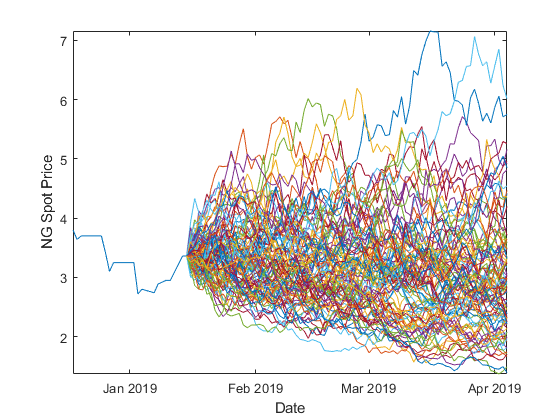

NTrials = 1000;
NSteps  = 2000;

Xsim = simulate(OUmodel, NSteps, 'NTrials', NTrials, 'DeltaTime', dt);
Xsim = squeeze(Xsim); % Remove redundant dimension
Ssim = exp(Xsim);

% This does the same as the lines above, but puts it all in a function we
% can reuse for different NTrials, and NSteps.  We will use this later.
simFcn = @(NSteps, NTrials) exp( squeeze( simulate(OUmodel, NSteps, 'NTrials', NTrials, 'DeltaTime', dt) ) );

% Visualize first 80 prices of 100 paths
plot(Dates(end-20:end), S(end-20:end), Dates(end)+days(0:79), Ssim(1:80,1:100));
xlabel('Date')
ylabel('NG Spot Price')
axis tight

## Save Model

The calibrated model is saved in a MAT-file for later use.

mkdir SavedModels

ngModel = struct('oumodel',OUmodel,'dt',dt,'simFcn',simFcn,'lastDate',Dates(end),'Freq','daily','Data',timetable(Dates,S))

ngModel = struct with fields:
     oumodel: [1×1 hwv]
          dt: 0.0038
      simFcn: @(NSteps,NTrials)exp(squeeze(simulate(OUmodel,NSteps,'NTrials',NTrials,'DeltaTime',dt)))
    lastDate: 15-Jan-2019 00:00:00
        Freq: 'daily'
        Data: [5565×1 timetable]


save SavedModels\NGPriceModel.mat -struct ngModel

## Visual Analysis of Simulated Price Paths

Instead of plotting a number of paths at once, we can plot longer single paths against the observed historical data to visually validate the simulated paths. This can serve as a final sanity check. 

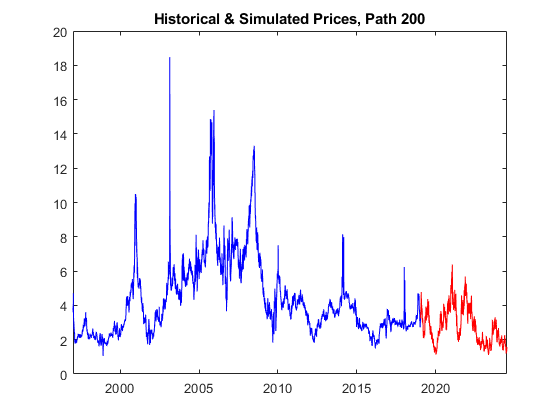

path = 200;
plot(Dates, S, 'b', Dates(end)+days(0:NSteps), Ssim(:,path), 'r');
title(['Historical & Simulated Prices, Path ' int2str(path)]);

## Automated Visualization for Calibration Report

This section creates plots of different simulations in an automated fashion to include in the calibration report.

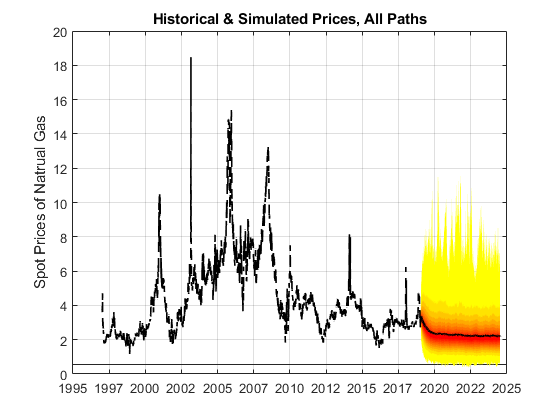

NTrials = 1000;
NSteps  = 2000;
Ssim = simFcn(NSteps, NTrials);

fanplot(table(Dates, S), [table(Dates(end)+days(0:NSteps)','VariableName',{'Dates'}),array2table(Ssim)], 'HistoricalMarker','none');
ylabel('Spot Prices of Natrual Gas')
title('Historical & Simulated Prices, All Paths');

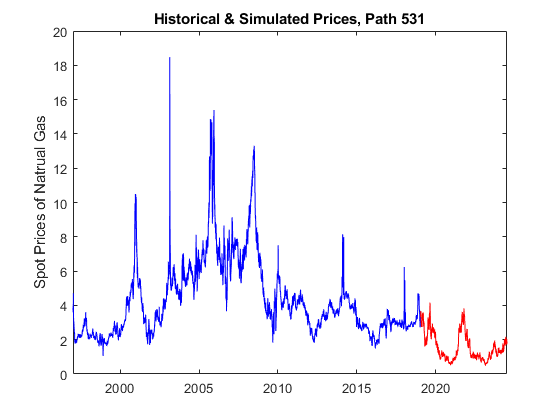

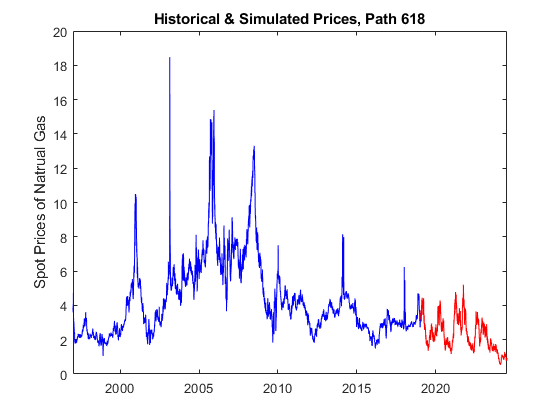

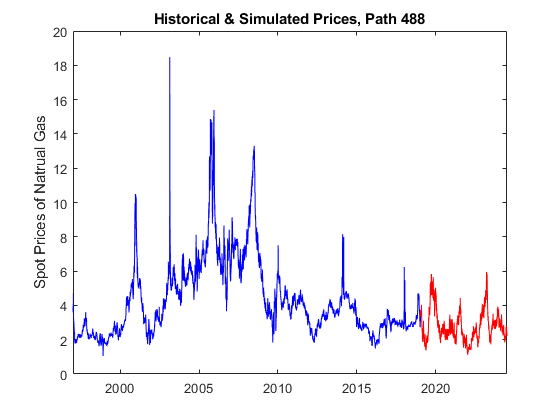

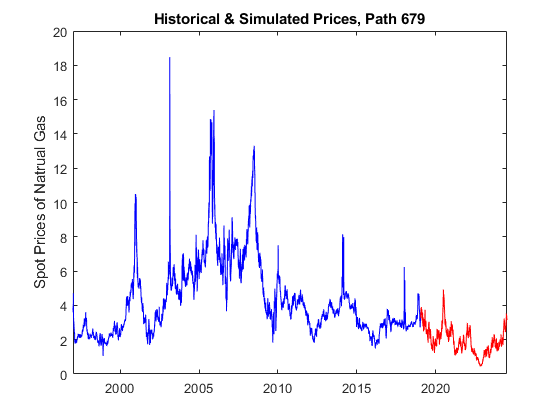

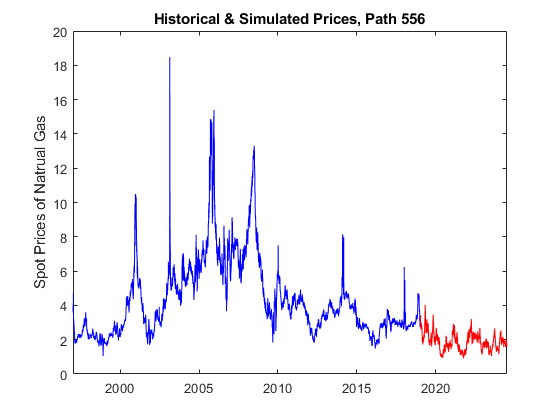

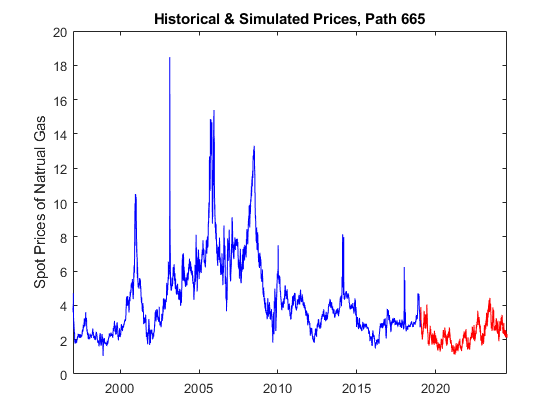

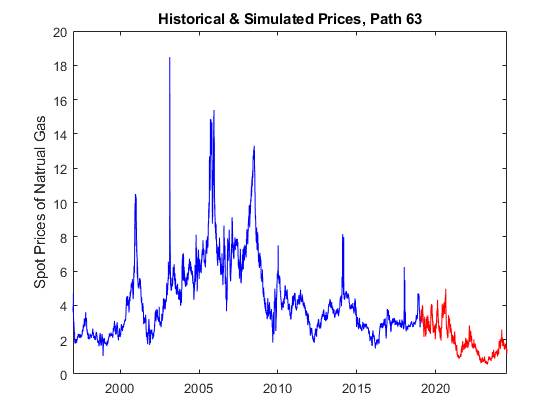

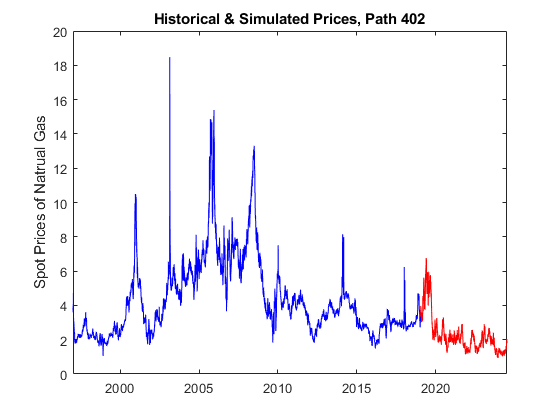


% Show 10 random paths from the simulation
for path = randi(NTrials,[1,10])
    figure
    plot(Dates, S, 'b', Dates(end)+(0:NSteps), Ssim(:,path), 'r');
    ylabel('Spot Prices of Natrual Gas')
    title(['Historical & Simulated Prices, Path ' int2str(path)]);
    snapnow;
end